### Solucion Analitica

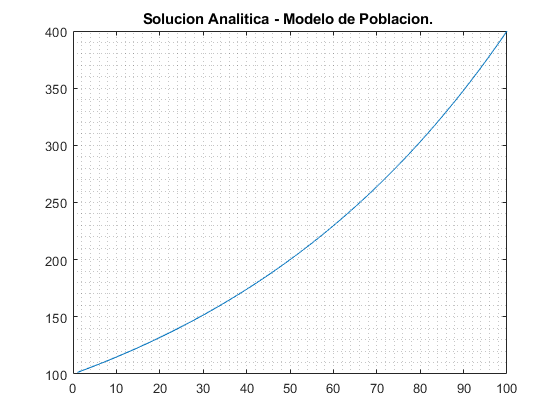

% Limpieza del espacio de trabajo
clearvars; % Borramos solo las variables del workspace
clf; % Borramos el area de las graficas

% Determinamos el diferencial de tiempo  
dt = 1; % 1 dia
%Para graficar la poblacion O contra el tiempo t
t = 1:dt:100; % establecemos el intervalo de 100 dias
P = @(t) 100*exp((log(2)/50 * t)); % traducimos la ecuaion poblacional
plot(t,P(t)); % graficamos de forma sencilla
grid minor;
title("Solucion Analitica - Modelo de Poblacion. ");


% ahora tenemos 100 valores en el vector de Poblacion P que podemos consultar.
fprintf("A los 50 dias la poblacion crecio a %4.2f y a los 100 dias son %4.2f. ", P(50), P(100));

A los 50 dias la poblacion crecio a 200.00 y a los 100 dias son 400.00. 

### Solucion Numerica

f = @(x,y) log(2)/50 * y; % Sabemos que f(x,y) = k * y , y k es (ln 2)/50.
h = 1; % un dia
inicio = 1; % dia 1 
fin = 100; % Dia 100
val_inicial = 100; % y(0) = 100

[x,y] = Met_Heun(f, h, inicio ,fin , val_inicial)

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y =   100.0000  101.3959  102.8113  104.2464  105.7016  107.1771  108.6732  110.1902  111.7283  113.2879  114.8693  116.4728  118.0986  119.7472  121.4187  123.1136  124.8322  126.5747  128.3416  130.1331  131.9496  133.7915  135.6591  137.5528  139.4729  141.4198  143.3939  145.3955  147.4251  149.4830  151.5697  153.6854  155.8307  158.0060  160.2116  162.4480  164.7156  167.0149  169.3462  171.7101  174.1071  176.5374  179.0017  181.5004  184.0340  186.6029  189.2077  191.8489  194.5269  197.2423


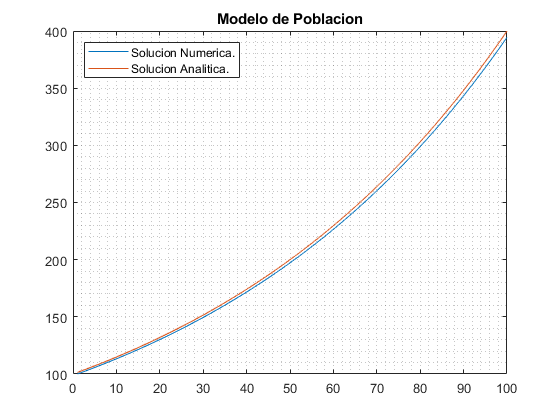

plot(x,y,"DisplayName","Solucion Numerica.");
hold on;
plot(t,P(t),"DisplayName","Solucion Analitica.");
hold off;
grid minor;
legend("location","northwest");
title("Modelo de Poblacion")


fprintf("A los 50 dias la poblacion crecio a %4.2f y a los 100 dias son %4.2f. ", y(50), y(100));

A los 50 dias la poblacion crecio a 197.24 y a los 100 dias son 394.48. 

### Error Relativo en Metodos Numericos

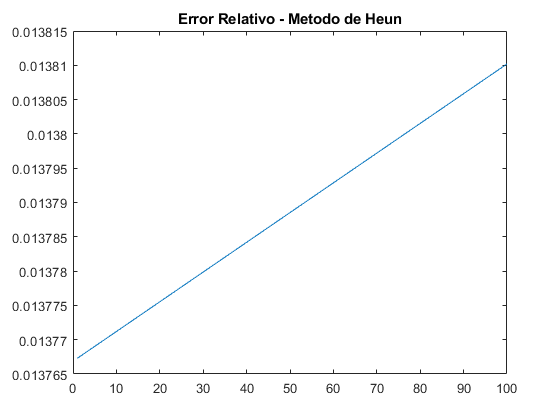

% Todo metodo numerico tien un porcentaje de error
% Podemos utilizar el Error Relativo comparando P (solucion analitica)
% contra y (solucion numerica)
error = abs((P(t) - y(t))./P(t));
plot(error);
title("Error Relativo - Metodo de Heun")

### Método de Heun

function [x,y] = Met_Heun(f, h, inicio ,fin , val_inicial)
    x = inicio:h:fin;
    y = zeros(1,length(x));
    y(1) = val_inicial;
    for i = 1:(length(x)-1)
        k_1 = f(x(i), y(i)); % se calcula k1
        k_2 = f(x(i) + h, y(i) + h * k_1); % se calcula k2
        
        y(i + 1) = y(i) + ((1/2) * k_1 + (1/2) * k_2) * h; %Ecuacion principal del método
    end

end